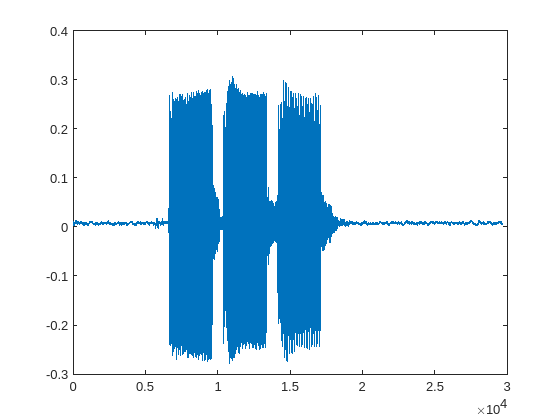

seq = importdata("output.csv");
plot(seq)

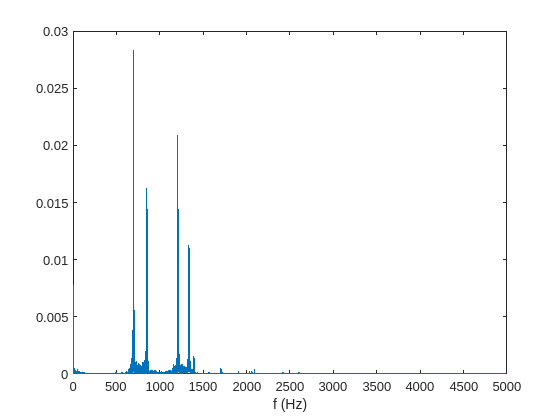

Fs = 10000;
T = 1/Fs;
L = 29696;
t = (0:L-1)*T;

Y = fft(seq);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1)
xlabel('f (Hz)')